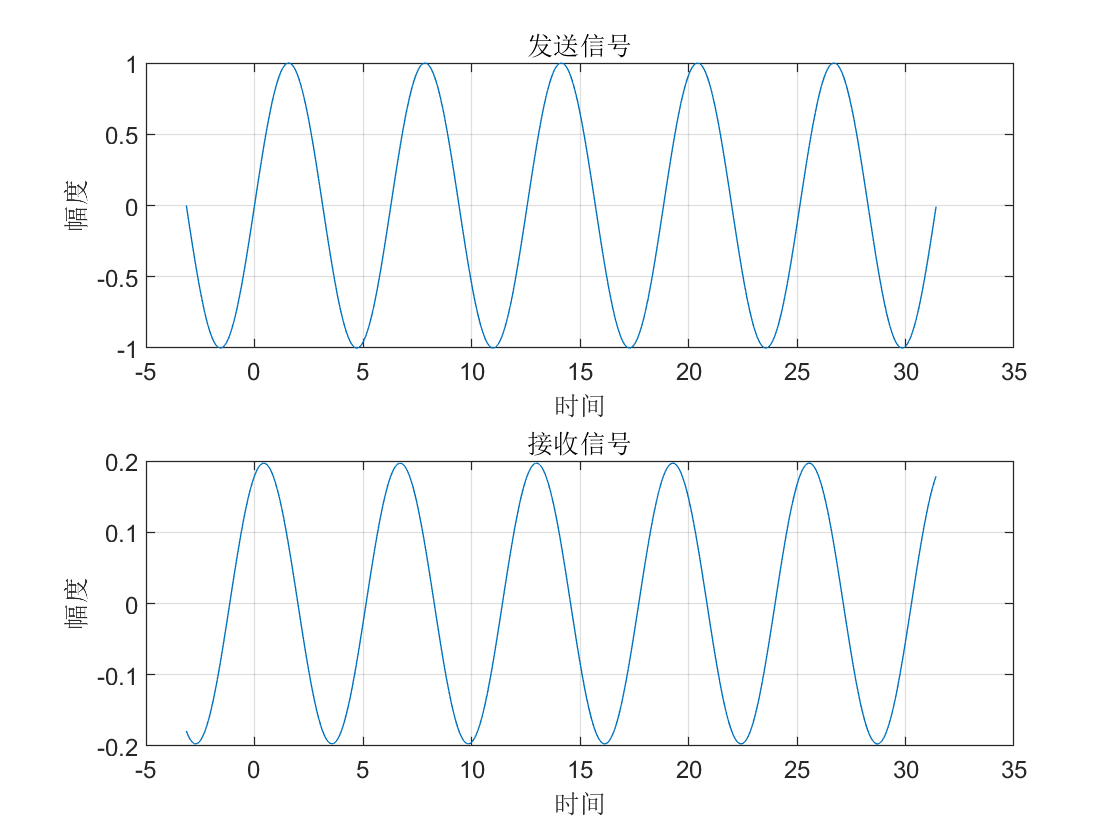

clear;
TimeStart=-pi;%起始时间
dt=0.01;%采样率
TimeEnd=10*pi;%终止时间
t=TimeStart:dt:TimeEnd;
distance1=500;%第一个障碍物多出的距离为5KM
distance2=1500;%第二个障碍物多出的距离为20KM
v_sound=340;%声音的传播速度340m/s
v_wave=3*10^8;%电磁波传播速度
alpha1=0.2;%第一条信道衰减系数
alpha2=0.3;%第二条信道衰减系数
alpha3=0.5;%第三条信道衰减系数
%sys=tf(1,1);%建立LTI系统模型
%h1=impulse(sys,t-5);%第一条路径的冲激响应
%h2=impulse(sys,t);%第一条路径的冲激响应
%h3=impulse(sys,t);%第一条路径的冲激响应
%h=h1+h2+h3;       %系统的冲激响应
%f1=sin(t)
subplot(2,1,1);
plot(t,f1(t));
xlabel('时间');
ylabel('幅度');
grid on;
title('发送信号');
xlabel('时间');
ylabel('幅度');


f=alpha1*f1(t)+alpha2*f1(t-distance1/v_sound)+alpha3*f1(t-distance2/v_sound);%响应表达式


subplot(2,1,2);
plot(t,f);
grid on;
title('接收信号');
xlabel('时间');
ylabel('幅度');